# Actividad 1.9 Landmarks 

Angel Estrada Centeno A01732584

Trayecto 1:

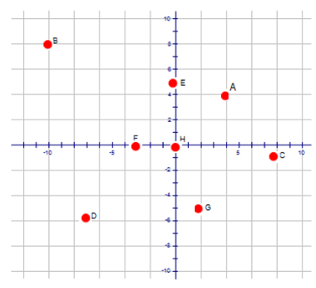

%% EXAMPLE: Differential drive vehicle following waypoints using the 
% Pure Pursuit algorithm
%
% Copyright 2018-2019 The MathWorks, Inc.

%% Define Vehicle
R = 0.1;                % Wheel radius [m]
L = 0.5;                % Wheelbase [m]
dd = DifferentialDrive(R,L);

%% Simulation parameters
sampleTime = 0.2;               % Sample time [s]
tVec = 0:sampleTime:100;         % Time array

initPose = [5;4;0];             % Initial pose (x y theta)
pose = zeros(3,numel(tVec));    % Pose matrix
pose(:,1) = initPose;

% Define waypoints
waypoints = [5,4; -10,8; 7.7,-1; -7,-4; -0.2,5; -3.2,0; 1.8,-5; 0,0];

% Create visualizer
viz = Visualizer2D;
viz.hasWaypoints = true;

%% Pure Pursuit Controller
controller = controllerPurePursuit;
controller.Waypoints = waypoints;
controller.LookaheadDistance = 0.35;
controller.DesiredLinearVelocity = 1;
controller.MaxAngularVelocity = 1.5;

%% Simulation loop
close all
r = rateControl(1/sampleTime);
for idx = 2:numel(tVec) 
    % Run the Pure Pursuit controller and convert output to wheel speeds
    [vRef,wRef] = controller(pose(:,idx-1));
    [wL,wR] = inverseKinematics(dd,vRef,wRef);
 
    
    % Compute the velocities
    [v,w] = forwardKinematics(dd,wL,wR);
    velB = [v;0;w]; % Body velocities [vx;vy;w]
    vel = bodyToWorld(velB,pose(:,idx-1));  % Convert from body to world
    
    % Perform forward discrete integration step
    pose(:,idx) = pose(:,idx-1) + vel*sampleTime; 
    
    % Update visualization
    viz(pose(:,idx),waypoints)
    waitfor(r);
    
end

Para este ejercicio se modificó, en primer lugar, los puntos objetivos; además de la duración del tiempo de simulación a 100 segundos para dar el tiempo suficiente a que el robot alcanzara todos los puntos. Además se ajustó el tiempo de muestreo a 0.2 segundos para dar un movimiento más veloz pero aún preciso del recorrido. 

Resultado

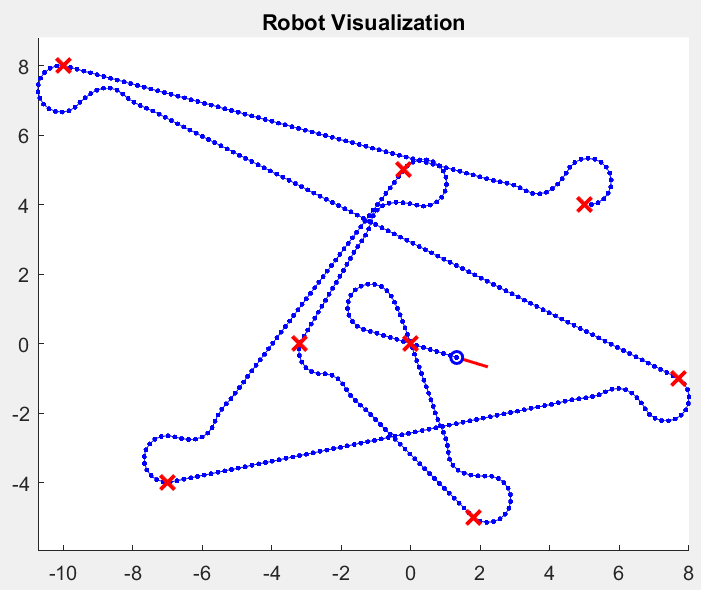

Trayecto 2 

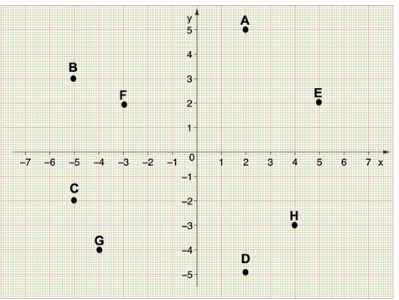

%% EXAMPLE: Differential drive vehicle following waypoints using the 
% Pure Pursuit algorithm
%
% Copyright 2018-2019 The MathWorks, Inc.

%% Define Vehicle
R = 0.1;                % Wheel radius [m]
L = 0.5;                % Wheelbase [m]
dd = DifferentialDrive(R,L);

%% Simulation parameters
sampleTime = 0.2;               % Sample time [s]
tVec = 0:sampleTime:55;         % Time array

initPose = [2;5;0];             % Initial pose (x y theta)
pose = zeros(3,numel(tVec));    % Pose matrix
pose(:,1) = initPose;

% Define waypoints
waypoints = [2,5; -5,3; -5,-2; 2,-5; 5,2; -3,2; -4,-4; 4,-3];

% Create visualizer
viz = Visualizer2D;
viz.hasWaypoints = true;

%% Pure Pursuit Controller
controller = controllerPurePursuit;
controller.Waypoints = waypoints;
controller.LookaheadDistance = 0.35;
controller.DesiredLinearVelocity = 1;
controller.MaxAngularVelocity = 1.5;

%% Simulation loop
close all
r = rateControl(1/sampleTime);
for idx = 2:numel(tVec) 
    % Run the Pure Pursuit controller and convert output to wheel speeds
    [vRef,wRef] = controller(pose(:,idx-1));
    [wL,wR] = inverseKinematics(dd,vRef,wRef);
 
    
    % Compute the velocities
    [v,w] = forwardKinematics(dd,wL,wR);
    velB = [v;0;w]; % Body velocities [vx;vy;w]
    vel = bodyToWorld(velB,pose(:,idx-1));  % Convert from body to world
    
    % Perform forward discrete integration step
    pose(:,idx) = pose(:,idx-1) + vel*sampleTime; 
    
    % Update visualization
    viz(pose(:,idx),waypoints)
    waitfor(r);
    
end

Para esta simulación se redujo el tiempo de simulación a 55 segundos, también se cambiaron los waypoints y se mantuvo un tiempo de muestreo de 0.2 segundos para hacer el trayecto más estable. 

Resultado

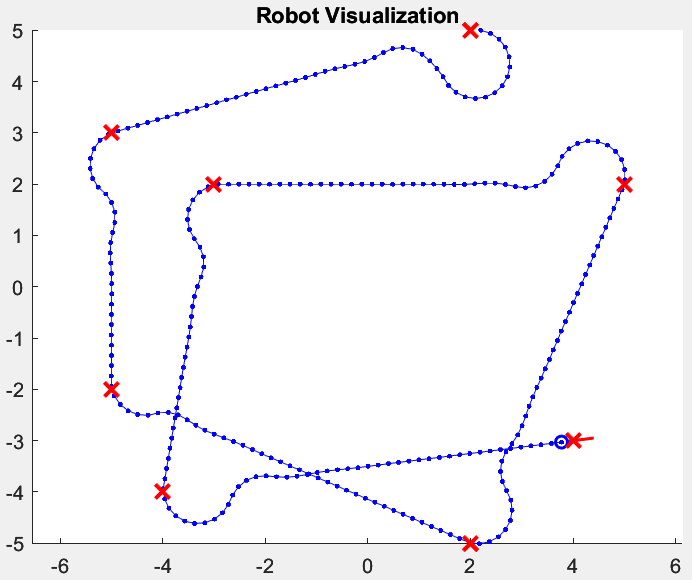

Trayecto 3

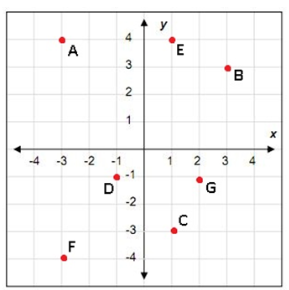

%% EXAMPLE: Differential drive vehicle following waypoints using the 
% Pure Pursuit algorithm
%
% Copyright 2018-2019 The MathWorks, Inc.

%% Define Vehicle
R = 0.1;                % Wheel radius [m]
L = 0.5;                % Wheelbase [m]
dd = DifferentialDrive(R,L);

%% Simulation parameters
sampleTime = 0.1;               % Sample time [s]
tVec = 0:sampleTime:42;         % Time array

initPose = [-3;4;0];             % Initial pose (x y theta)
pose = zeros(3,numel(tVec));    % Pose matrix
pose(:,1) = initPose;

% Define waypoints
waypoints = [-3,4; 3,3; 1,-3; -1,-1; 1,4; -3,-4; 2,-1];

% Create visualizer
viz = Visualizer2D;
viz.hasWaypoints = true;

%% Pure Pursuit Controller
controller = controllerPurePursuit;
controller.Waypoints = waypoints;
controller.LookaheadDistance = 0.35;
controller.DesiredLinearVelocity = 1;
controller.MaxAngularVelocity = 1.5;

%% Simulation loop
close all
r = rateControl(1/sampleTime);
for idx = 2:numel(tVec) 
    % Run the Pure Pursuit controller and convert output to wheel speeds
    [vRef,wRef] = controller(pose(:,idx-1));
    [wL,wR] = inverseKinematics(dd,vRef,wRef);
 
    
    % Compute the velocities
    [v,w] = forwardKinematics(dd,wL,wR);
    velB = [v;0;w]; % Body velocities [vx;vy;w]
    vel = bodyToWorld(velB,pose(:,idx-1));  % Convert from body to world
    
    % Perform forward discrete integration step
    pose(:,idx) = pose(:,idx-1) + vel*sampleTime; 
    
    % Update visualization
    viz(pose(:,idx),waypoints)
    waitfor(r);
    
end

Para esta simulación se ajustó el tiempo total del recorrido así como el tiempo de muestreo pues al hacerlo más corto se obtiene una mejor trayectoria, más lineal y con menos oscilaciones. 

Resultado

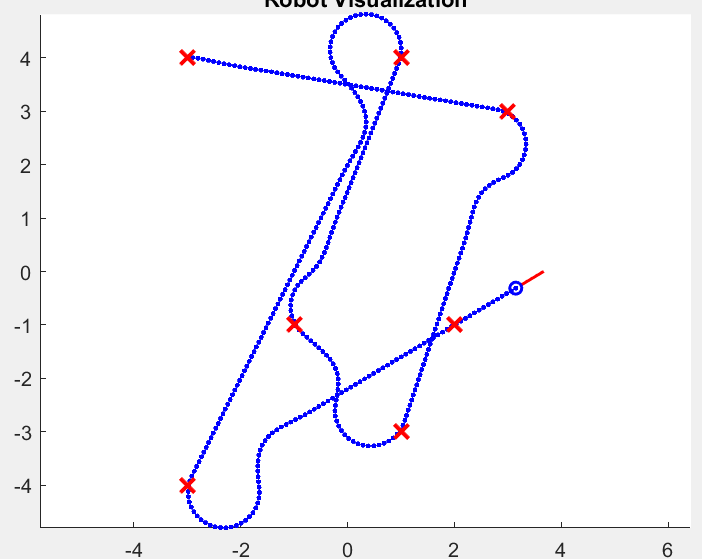

WAYPOINTS

Para las siguientes 3 nuevas trayectorias ya dadas se calcularán primero los waypoints y después se recreará la trayectoria completa. 

Figura 1

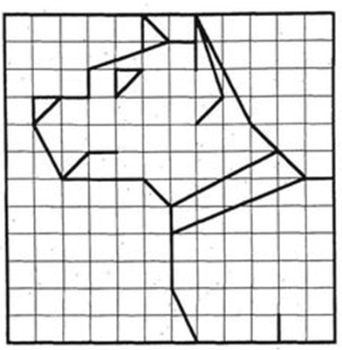

%% EXAMPLE: Differential drive vehicle following waypoints using the 
% Pure Pursuit algorithm
%
% Copyright 2018-2019 The MathWorks, Inc.

%% Define Vehicle
R = 0.1;                % Wheel radius [m]
L = 0.5;                % Wheelbase [m]
dd = DifferentialDrive(R,L);

%% Simulation parameters
sampleTime = 0.005;               % Sample time [s]
tVec = 0:sampleTime:40;         % Time array

initPose = [6;0;-pi];             % Initial pose (x y theta)
pose = zeros(3,numel(tVec));    % Pose matrix
pose(:,1) = initPose;

% Define waypoints
waypoints = [6,0; 5,0; 4,1; 3,2; 1,6; 1,5; 0,5; -1,6; -1,4.5; -2,4.3; -3,4; -3,3; -5,3; -5,2; -4,0; -1,0; 0,-1; 4,1; 5,0; 0,-2; 0,-4; 1,-6];

% Create visualizer
viz = Visualizer2D;
viz.hasWaypoints = true;

%% Pure Pursuit Controller
controller = controllerPurePursuit;
controller.Waypoints = waypoints;
controller.LookaheadDistance = 0.25;
controller.DesiredLinearVelocity = 1;
controller.MaxAngularVelocity = 15.5;

%% Simulation loop
close all
r = rateControl(1/sampleTime);
for idx = 2:numel(tVec) 
    % Run the Pure Pursuit controller and convert output to wheel speeds
    [vRef,wRef] = controller(pose(:,idx-1));
    [wL,wR] = inverseKinematics(dd,vRef,wRef);
 
    
    % Compute the velocities
    [v,w] = forwardKinematics(dd,wL,wR);
    velB = [v;0;w]; % Body velocities [vx;vy;w]
    vel = bodyToWorld(velB,pose(:,idx-1));  % Convert from body to world
    
    % Perform forward discrete integration step
    pose(:,idx) = pose(:,idx-1) + vel*sampleTime; 
    
    % Update visualization
    viz(pose(:,idx),waypoints)
    waitfor(r);
    
end


Para esta figura se tuvo que minimizar el tiempo de muestreo significativamente para obtener un trazo recto y sin oscilaciones, también se amplió el tiempo total del programa y se incrementó en un 1500% la velocidad angular para los giros más pronunciados como en las orejas del perro que no son del todo rectas pero la curva es la menor posible. 

Resultado

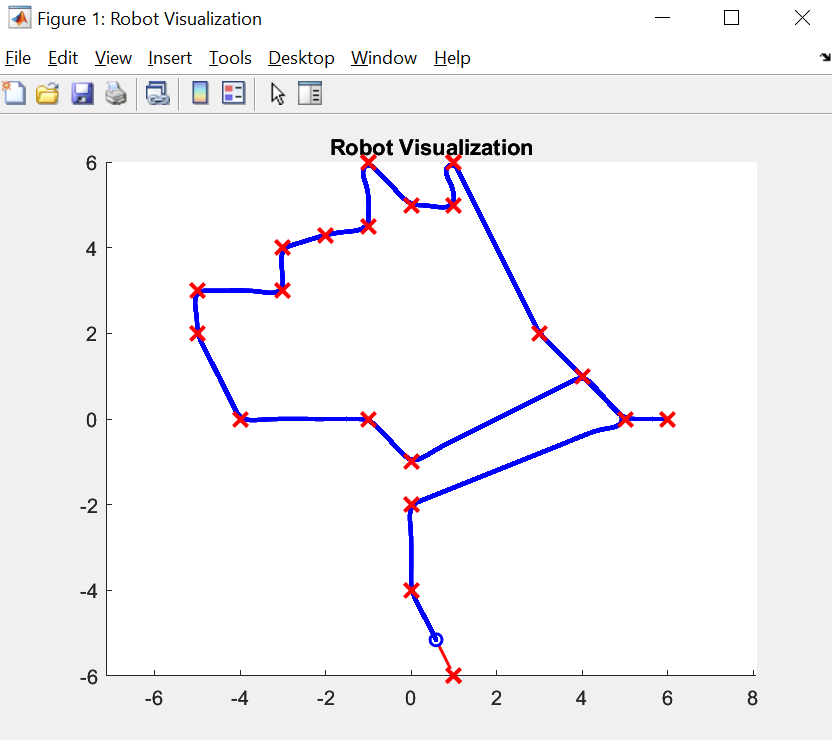

Figura 2

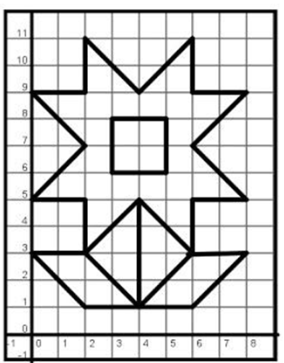

%% EXAMPLE: Differential drive vehicle following waypoints using the 
% Pure Pursuit algorithm
%
% Copyright 2018-2019 The MathWorks, Inc.

%% Define Vehicle
R = 0.1;                % Wheel radius [m]
L = 0.5;                % Wheelbase [m]
dd = DifferentialDrive(R,L);

%% Simulation parameters
sampleTime = 0.01;               % Sample time [s]
tVec = 0:sampleTime:72;         % Time array

initPose = [4;5;pi/2];             % Initial pose (x y theta)
pose = zeros(3,numel(tVec));    % Pose matrix
pose(:,1) = initPose;

% Define waypoints
waypoints = [4,5; 4,6; 5,6; 5,8; 3,8; 3,6; 4,6; 4,5; 6,3; 6,5; 8,5; 6,7; 8,9; 6,9; 6,11; 4,9; 2,11; 2,9; 0,9; 2,7; 0,5; 2,5; 2,3; 4,5; 4,1; 2,3; 0,3; 2,1; 6,1; 8,3; 6,3; 4,1];

% Create visualizer
viz = Visualizer2D;
viz.hasWaypoints = true;

%% Pure Pursuit Controller
controller = controllerPurePursuit;
controller.Waypoints = waypoints;
controller.LookaheadDistance = 0.15;
controller.DesiredLinearVelocity = 1;
controller.MaxAngularVelocity = 15.5;

%% Simulation loop
close all
r = rateControl(1/sampleTime);
for idx = 2:numel(tVec) 
    % Run the Pure Pursuit controller and convert output to wheel speeds
    [vRef,wRef] = controller(pose(:,idx-1));
    [wL,wR] = inverseKinematics(dd,vRef,wRef);
 
    
    % Compute the velocities
    [v,w] = forwardKinematics(dd,wL,wR);
    velB = [v;0;w]; % Body velocities [vx;vy;w]
    vel = bodyToWorld(velB,pose(:,idx-1));  % Convert from body to world
    
    % Perform forward discrete integration step
    pose(:,idx) = pose(:,idx-1) + vel*sampleTime; 
    
    % Update visualization
    viz(pose(:,idx),waypoints)
    waitfor(r);
    
end

Para esta figura primero se calcularon los waypoints en el mapa que son las vértices de la figura. Posteriormente se ajustó el tiempo total de la simulación para poder ver el trayecto completo; así como el tiempo de muestreo que no se requirió una tan pequeño por el tamaño de la figura en el área. Se redujo la distancia de visión de frente porque los waypoints están más cerca entre sí y de este modo se le da mayor exactitud al modelo con sus sobretiros y líneas rectas. 

Resultado

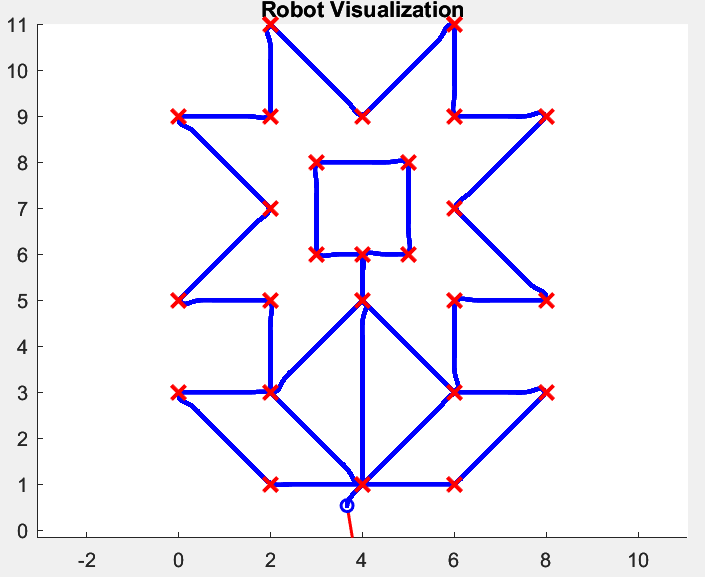

Figura 3

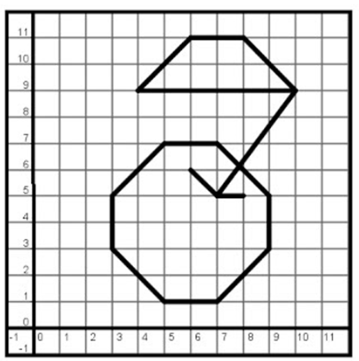

%% EXAMPLE: Differential drive vehicle following waypoints using the 
% Pure Pursuit algorithm
%
% Copyright 2018-2019 The MathWorks, Inc.

%% Define Vehicle
R = 0.1;                % Wheel radius [m]
L = 0.5;                % Wheelbase [m]
dd = DifferentialDrive(R,L);

%% Simulation parameters
sampleTime = 0.01;               % Sample time [s]
tVec = 0:sampleTime:43;         % Time array

initPose = [6;6;-pi/4];             % Initial pose (x y theta)
pose = zeros(3,numel(tVec));    % Pose matrix
pose(:,1) = initPose;

% Define waypoints
waypoints = [6,6; 7,5; 10,9; 8,11; 6,11; 4,9; 10,9; 7.9,6.1; 9,5; 9,3; 7,1; 5,1; 3,3; 3,5; 5,7; 7,7; 7.9,6.1];

% Create visualizer
viz = Visualizer2D;
viz.hasWaypoints = true;

%% Pure Pursuit Controller
controller = controllerPurePursuit;
controller.Waypoints = waypoints;
controller.LookaheadDistance = 0.15;
controller.DesiredLinearVelocity = 1;
controller.MaxAngularVelocity = 15.5;

%% Simulation loop
close all
r = rateControl(1/sampleTime);
for idx = 2:numel(tVec) 
    % Run the Pure Pursuit controller and convert output to wheel speeds
    [vRef,wRef] = controller(pose(:,idx-1));
    [wL,wR] = inverseKinematics(dd,vRef,wRef);
 
    
    % Compute the velocities
    [v,w] = forwardKinematics(dd,wL,wR);
    velB = [v;0;w]; % Body velocities [vx;vy;w]
    vel = bodyToWorld(velB,pose(:,idx-1));  % Convert from body to world
    
    % Perform forward discrete integration step
    pose(:,idx) = pose(:,idx-1) + vel*sampleTime; 
    
    % Update visualization
    viz(pose(:,idx),waypoints)
    waitfor(r);
    
end


Para esta figura se definieron los nuevos waypoints como las vértices de la figura, después se ajustó el tiempo total de la simulación y se mantuvieron el tiempo de muestreo y la distancia de visión del ejercicio pasado. 

Resultado